# **GFL・GFMの組み合わせ最適選択をしてみよう !!**

## 先ほどと同じようにGUILDAに実装済みの標準モデルを呼び出してみましょう !!

net = network.IEEE14bus;  

INFO: Slack bus not found. Setting the first bus 'B001' as the slack bus.
INFO: B001 set as slack bus. 
      P and Q specifications for SG1B001 ignored in powerflow calculation.


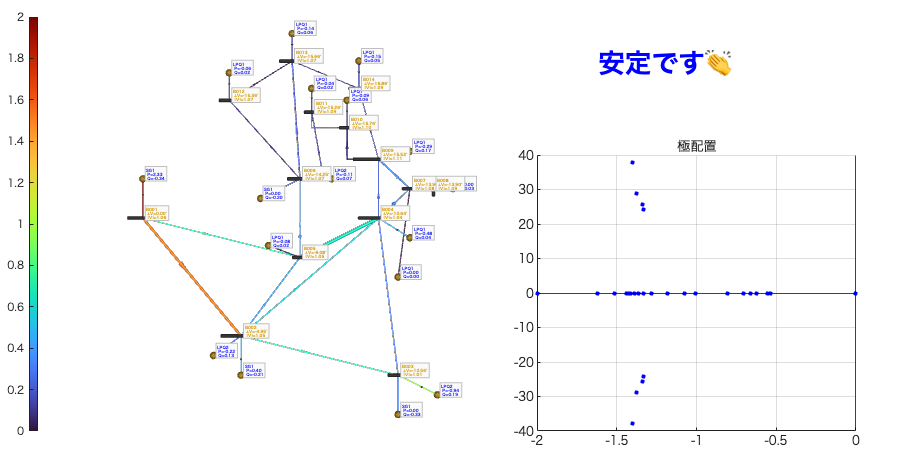

 >> グラフプロットに反映中... ok!!
 >> 極配置プロットに反映中... ok!!


INV_past = repmat(2,[1,4]);
base_comp_name = ["LPQ2B003","LPQ1B009","LPQ1B012","LPQ1B014"];

a_Comp   = tools.vcellfun(@(b) b.a_Component, net.a_Bus);
get_PQ   = @(p) [p.P, p.Q];
rv_defPQ = tools.vcellfun(@(c) get_PQ(c.para_powerflow), a_Comp);
[Graph, txt, sct] = func.new_plot(net);
func.update_plot(net, Graph, txt, sct);

## なんか凄そうなグラフが出てきましたね。

#### 左のグラフは系統図を表しています。

#### 系統内に流れている潮流の大きさや各送電線における電力の流れやすさが可視化されていて分かりやすいですね。

#### 次に、右のグラフを見てみましょう。これは、IEEE14母線系統を平衡点周りで近似線形化したシステムのA行列の固有値を見ています。

#### 制御を勉強している人なら分かると思いますが、線形システムが安定であることと、A行列の固有値が複素平面上の左半平面に存在することは

#### 等価でしたね。上記のグラフを見てみると、ゼロ固有値を除いたすべての固有値が左半平面上に存在することから安定であることが分かります。

## では次に、負荷の比率を増減させてみましょう

#### 下にalphaという変数があります。これは、系統に接続されているすべての負荷をalpha倍するためのものです。

#### 適当な値を選んで、実行を押してみましょう。

net = IEEE14bus;

INFO: Slack bus not found. Setting the first bus 'B001' as the slack bus.
INFO: B001 set as slack bus. 
      P and Q specifications for SG1B001 ignored in powerflow calculation.


a_Comp   = tools.vcellfun(@(b) b.a_Component, net.a_Bus);
alpha =2.18 

alpha = 2.1800

mulitiple_alpha(a_Comp, rv_defPQ, alpha)
fprintf(" >> 潮流計算中          ...")

 >> 潮流計算中          ...

net.initialize;
disp(" ok!!")

 ok!!


 >> グラフプロットに反映中... ok!!
 >> 極配置プロットに反映中... ok!!


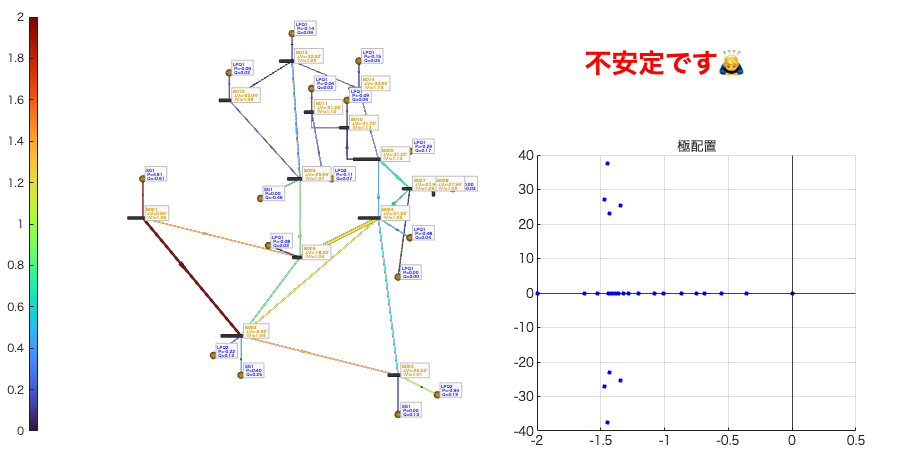

% sct = func.update_plot(net, Graph, txt, ax_eig, sct);
func.update_plot(net, Graph, txt, sct);

## 結果が出ましたね

#### 指定した負荷の比率によっては系統が不安定化した人もいると思います。

#### このように、同じシステムを対象にしていたとしても、潮流設定によって安定度が変化することが分かります。

# **系統の構成を変更して最大の倍率を求めてみよう !!**

#### **図のように母線3,9,12,14ではGFM,GFLの選択ができるようになっています。**

#### **自由に機器を選択して、系統の挙動がどのように変わるのか確認してみましょう。**

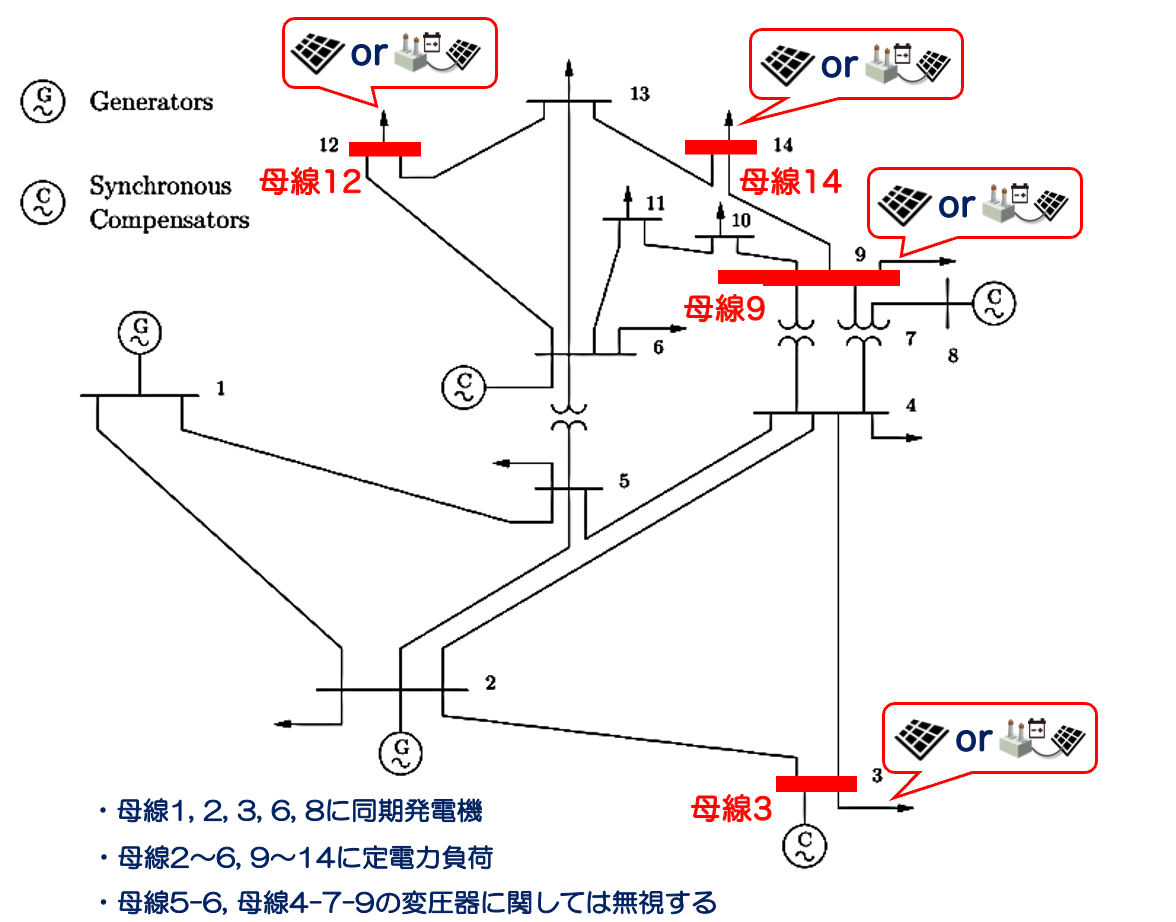

net = IEEE14bus;
a_Comp2  = tools.vcellfun(@(b) b.a_Component, net.a_Bus);
base_bus = net.a_Bus([3,9,12,14]);

INV1 = 1;
INV2 = 1;
INV3 = 1;
INV4 = 1;

alpha2 =3.19;
 

inv_list = [INV1;INV2;INV3;INV4];

cmp_list = ["gen-classical";"load-power"];

tab_param = table(10,20,1.6,0.9, 'VariableNames', {'M','D','Xd','Xq'});
for inv = 1:numel(inv_list)
    base_name = base_comp_name(inv);
    new_comp  = cmp_list( inv_list(inv) );
    str_tagComp = string(base_bus{inv}.a_Component);
    base_bus{inv}.replace_component(base_name, new_comp, tab_param );    
end
mulitiple_alpha(a_Comp2, rv_defPQ, alpha2);

net.initialize;

[Graph2, txt2, sct2] = func.new_plot(net);
func.update_plot(net, Graph2, txt2, sct2);

#### GFL・GFMを切り替えることによって系統がその程度の負荷変動を許容量が変化したと思います。

# **GFL・GFMの組み合わせ最適選択をしてみよう !!**

#### **先ほどの説明では以下の式の正負が系統の安定性に深く関わっていました。**

 

#### **今度は上記の式が非負ならGFM、負ならGFLを選ぶことによって系統の安定度を最大化してみましょう。**

### **まずは、GFMのパラメータを設定します。設定が完了したら、計算を押してみましょう。**

net = IEEE14bus;
a_Comp2  = tools.vcellfun(@(b) b.a_Component, net.a_Bus);
base_bus = net.a_Bus([3,9,12,14]);

**母線3に接続するGFMのパラメータ**

Xd3 = 0.85;
Xq3 = 0.45;

**母線9に接続するGFMのパラメータ**

Xd9 = 1;
Xq9 = 1;

**母線12に接続するGFMのパラメータ**

Xd12 = 0.64;
Xq12 = 0.32;

**母線14に接続するGFMのパラメータ**

Xd14 = 1.2;
Xq14 = 0.8;

 

Is = zeros(4,1);
for IS = 1:4
    Is(IS) = base_bus{IS}.a_Component{end}.c_Iequilibrium;
end
Vs = cellfun(@(BS) BS.c_Vequilibrium, base_bus);
Ps = arrayfun(@(VS, IS) real(VS*conj(IS)), Vs, Is);
Qs = arrayfun(@(VS, IS) imag(VS*conj(IS)), Vs, Is);

Vabs = arrayfun(@(VS) abs(VS), Vs);

XQ = [Xq3;Xq9;Xq12;Xq14];
XD = [Xd3;Xd9;Xd12;Xd14];

GFMterm = arrayfun(@(PS, QS, VS, XQs, XDs) calc_GFMterm(PS, QS, VS, XQs, XDs), Ps, Qs, Vabs, XQ, XD);

iv_GFMT = [3,9,12,14];
for GFMT = 1:4
    disp("母線"+iv_GFMT(GFMT)+"における(*)の計算結果: "+string(GFMterm(GFMT)))
end

### 計算結果が出ましたね。ではその結果に基づいて、GFM・GFLの選択をしてみましょう。

TAB = table(10*ones(4,1), 2*ones(4,1), XQ, XD, 'VariableNames', {'M', 'D', 'Xq', 'Xd'});
INV1 = 2;
INV2 = 2;
INV3 = 2;
INV4 = 2;
 

inv_list = [INV1;INV2;INV3;INV4];

cmp_list = ["gen-classical";"load-power"];
for inv = 1:numel(inv_list)
    base_name = base_comp_name(inv);
    new_comp  = cmp_list( inv_list(inv) );
    str_tagComp = string(base_bus{inv}.a_Component);
    base_bus{inv}.replace_component(base_name, new_comp, TAB(inv,:) );  
end

### **次に、先ほどのようにalphaを変動させてみましょう。**

alpha3 =2.58 ;
mulitiple_alpha(a_Comp, rv_defPQ, alpha)
net.initialize;

[Graph3, txt3, sct3] = func.new_plot(net);
func.update_plot(net, Graph3, txt3, sct3);

## **最適選択の結果、適当にGFM・GFLの選択を行った時よりも安定度が向上していればGOODです !!**

function beta = calc_beta(Q, V, Xq)
    beta = Q + V^2/Xq;
end

function phi = calc_phi(P, Q, V, Xq)
    beta = calc_beta(Q, V, Xq);
    phi  = atan2(P, beta);
end

function gamma = calc_gamma(P, Q, V, Xq, Xd)
    phi = calc_phi(P, Q, V, Xq);
    gamma = Q + V^2*cos(phi)^2/Xq + V^2*sin(phi)^2/Xd;
end

function GFMterm = calc_GFMterm(P, Q, V, Xq, Xd)
    gamma = calc_gamma(P, Q, V, Xq, Xd);
    beta  = calc_beta(Q, V, Xq);
    phi   = calc_phi(P, Q, V, Xq);

    GFMterm = (gamma*beta + beta^2 - P^2)/(gamma * (V*sin(phi))^2) + 2/Xq;
end

function mulitiple_alpha(a_Comp, rv_defPQ, alpha)
    for i_Comp = 1:numel(a_Comp)
        para_pf = a_Comp{i_Comp}.para_powerflow;
        para_pf.P = rv_defPQ(i_Comp,1) * alpha;
        para_pf.Q = rv_defPQ(i_Comp,2) * alpha;
    end
end

